close all
clear
clc

syms x y t r phi z real
syms e n beta mu_0 c omega real positive
syms pi

% % Magnetic vector potential (without limit of Bessel function)
% Az=(-e)*mu_0/(2*pi)^2*...
%    besselk(0,1i*omega/c*sqrt(n^2-beta^(-2))*r)*...
%    exp(-1i*omega/(beta*c)*z)

% Magnetic vector potential (with limit of Bessel function)
Az=(-e)*mu_0/(2*pi)^2*...
   sqrt(pi/(2*omega/c*sqrt(n^2-beta^(-2))*r))*exp(-1i*pi/4)*exp(-1i*omega/c*sqrt(n^2-beta^(-2))*r)*...
   exp(-1i*omega/(beta*c)*z)

$$Az = \frac{\sqrt{2}\,\sqrt{c}\,e\,\mu_{0}\,{\mathrm{e}}^{-\frac{\omega \,r\,\sqrt{n^{2}-\frac{1}{\beta^{2}}}\,\mathrm{i}}{c}}\,{\mathrm{e}}^{-\frac{\omega \,z\,\mathrm{i}}{\beta \,c}}\,\sqrt{\frac{1}{2\,r\,\sqrt{n^{2}-\frac{1}{\beta^{2}}}}}\,\left(-\frac{1}{8}+\frac{1}{8}\,\mathrm{i}\right)}{\sqrt{\omega }\,\pi^{3/2}}$$


% Check derivatives of magnetic vector potential
check_diff_Az_z=simplify(...
                diff(Az,z)-...
                (-1i*omega/(beta*c))*Az)

$$check\_diff\_Az\_z = 0$$

check_diff_Az_r=simplify(...
                diff(Az,r)-...
                (-1i*omega/c*sqrt(n^2-beta^(-2))-1/(2*r))*Az)

$$check\_diff\_Az\_r = 0$$


% Derive electric field from the potentials
Er=simplify(-c/(n^2*beta)*diff(Az,r))

$$Er = -\frac{\sqrt{c}\,e\,\mu_{0}\,{\mathrm{e}}^{-\frac{\omega \,\left(z\,\mathrm{i}+r\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}\right)}{\beta \,c}}\,\left(\beta \,c\,\left(1-\mathrm{i}\right)+\omega \,r\,\sqrt{\beta^{2}\,n^{2}-1}\,\left(2+2\,\mathrm{i}\right)\right)}{16\,\beta^{3/2}\,n^{2}\,\sqrt{\omega }\,r^{2}\,\pi^{3/2}\,\sqrt{\beta^{2}\,n^{2}-1}\,\sqrt{\frac{1}{r\,\sqrt{\beta^{2}\,n^{2}-1}}}}$$

Ez=simplify(-1i*omega*Az-c/(n^2*beta)*diff(Az,z))

$$Ez = \frac{\sqrt{c}\,e\,\mu_{0}\,\sqrt{\omega }\,{\mathrm{e}}^{-\frac{\omega \,\left(z\,\mathrm{i}+r\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}\right)}{\beta \,c}}\,\left(\beta^{2}\,n^{2}\,\left(1+\mathrm{i}\right)-1-\mathrm{i}\right)\,\sqrt{\frac{1}{r\,\sqrt{\beta^{2}\,n^{2}-1}}}}{8\,\beta^{3/2}\,n^{2}\,\pi^{3/2}}$$


% Derive magnetic field from the potentials
Bpconj=simplify(-diff(conj(Az),r))

$$Bpconj = -\frac{e\,\mu_{0}\,{\mathrm{e}}^{\frac{\omega \,\left(z\,\mathrm{i}+r\,\bar{\sqrt{\beta^{2}\,n^{2}-1}}\,\mathrm{i}\right)}{\beta \,c}}\,\left(\left(2-2\,\mathrm{i}\right)\,\omega \,r^{2}\,{\bar{\sqrt{\beta^{2}\,n^{2}-1}}}^{2}\,{\bar{\sqrt{\frac{1}{r\,\sqrt{\beta^{2}\,n^{2}-1}}}}}^{2}+\beta \,c\,\left(1+\mathrm{i}\right)\right)}{16\,\sqrt{\beta }\,\sqrt{c}\,\sqrt{\omega }\,r^{2}\,\pi^{3/2}\,\bar{\sqrt{\beta^{2}\,n^{2}-1}}\,\bar{\sqrt{\frac{1}{r\,\sqrt{\beta^{2}\,n^{2}-1}}}}}$$

Hp=simplify(1/mu_0*conj(Bpconj))

$$Hp = -\frac{e\,{\mathrm{e}}^{-\frac{\omega \,\left(z\,\mathrm{i}+r\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}\right)}{\beta \,c}}\,\left(\beta \,c\,\left(1-\mathrm{i}\right)+\omega \,r\,\sqrt{\beta^{2}\,n^{2}-1}\,\left(2+2\,\mathrm{i}\right)\right)}{16\,\sqrt{\beta }\,\sqrt{c}\,\sqrt{\omega }\,r^{2}\,\pi^{3/2}\,\sqrt{\beta^{2}\,n^{2}-1}\,\sqrt{\frac{1}{r\,\sqrt{\beta^{2}\,n^{2}-1}}}}$$


% Assume r>0 to simplify the expressions
assume(r,'positive')

% Equation B8
EqB8=simplify(real(-1/mu_0*Ez*Bpconj));
EqB8=simplify(expand(EqB8))

$$EqB8 = \left\{ \begin{array}{cl} 0 & \text{ if }\beta^{2}\,n^{2}<1\\ \frac{e^{2}\,\mu_{0}\,\omega \,\left(\beta^{2}\,n^{2}-1\right)}{32\,\beta^{2}\,n^{2}\,r\,\pi^{3}} & \text{ if }1\leq \beta^{2}\,n^{2} \end{array}\right.$$


% Equation B9
EqB9_dW_dzdw=simplify(4*2*pi*2*pi*r*EqB8/2)

$$EqB9\_dW\_dzdw = \left\{ \begin{array}{cl} 0 & \text{ if }\beta^{2}\,n^{2}<1\\ \frac{e^{2}\,\mu_{0}\,\omega \,\left(\beta^{2}\,n^{2}-1\right)}{4\,\beta^{2}\,n^{2}\,\pi } & \text{ if }1\leq \beta^{2}\,n^{2} \end{array}\right.$$


% Impose analytical solution
Hw= subs(Hp,[r,z],[abs(y),x]).*sign(y)

$$Hw = -\frac{e\,{\mathrm{e}}^{-\frac{\omega \,\left(x\,\mathrm{i}+\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}\right)}{\beta \,c}}\,\mathrm{sign}\left(y\right)\,\left(\beta \,c\,\left(1-\mathrm{i}\right)+\omega \,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\left(2+2\,\mathrm{i}\right)\right)}{16\,\sqrt{\beta }\,\sqrt{c}\,\sqrt{\omega }\,\pi^{3/2}\,{\left|y\right|}^{2}\,\sqrt{\frac{1}{\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}}}\,\sqrt{\beta^{2}\,n^{2}-1}}$$

Ew=[subs(Ez,[r,z],[abs(y),x])
    subs(Er,[r,z],[abs(y),x]).*sign(y)]

$$Ew = \left[\begin{array}{c} \frac{\sqrt{c}\,e\,\mu_{0}\,\sqrt{\omega }\,{\mathrm{e}}^{-\frac{\omega \,\left(x\,\mathrm{i}+\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}\right)}{\beta \,c}}\,\sqrt{\frac{1}{\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}}}\,\left(\beta^{2}\,n^{2}\,\left(1+\mathrm{i}\right)-1-\mathrm{i}\right)}{8\,\beta^{3/2}\,n^{2}\,\pi^{3/2}}\\ -\frac{\sqrt{c}\,e\,\mu_{0}\,{\mathrm{e}}^{-\frac{\omega \,\left(x\,\mathrm{i}+\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}\right)}{\beta \,c}}\,\mathrm{sign}\left(y\right)\,\left(\beta \,c\,\left(1-\mathrm{i}\right)+\omega \,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\left(2+2\,\mathrm{i}\right)\right)}{16\,\beta^{3/2}\,n^{2}\,\sqrt{\omega }\,\pi^{3/2}\,{\left|y\right|}^{2}\,\sqrt{\frac{1}{\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}}}\,\sqrt{\beta^{2}\,n^{2}-1}} \end{array}\right]$$


% Conversion to variables used by Szczepkowicz
f=2; omega=2*pi*f; beta=1; n=2; c=1; mu_0=1; e=1;

% Plot Ewx
Ewx=eval(Ew(1))

$$Ewx = \frac{{\mathrm{e}}^{-4\,\pi \,\left(x\,\mathrm{i}+\sqrt{3}\,\left|y\right|\,\mathrm{i}\right)}\,\sqrt{4\,\pi }\,\sqrt{\frac{\sqrt{3}}{3\,\left|y\right|}}\,\left(\frac{3}{32}+\frac{3}{32}\,\mathrm{i}\right)}{\pi^{3/2}}$$

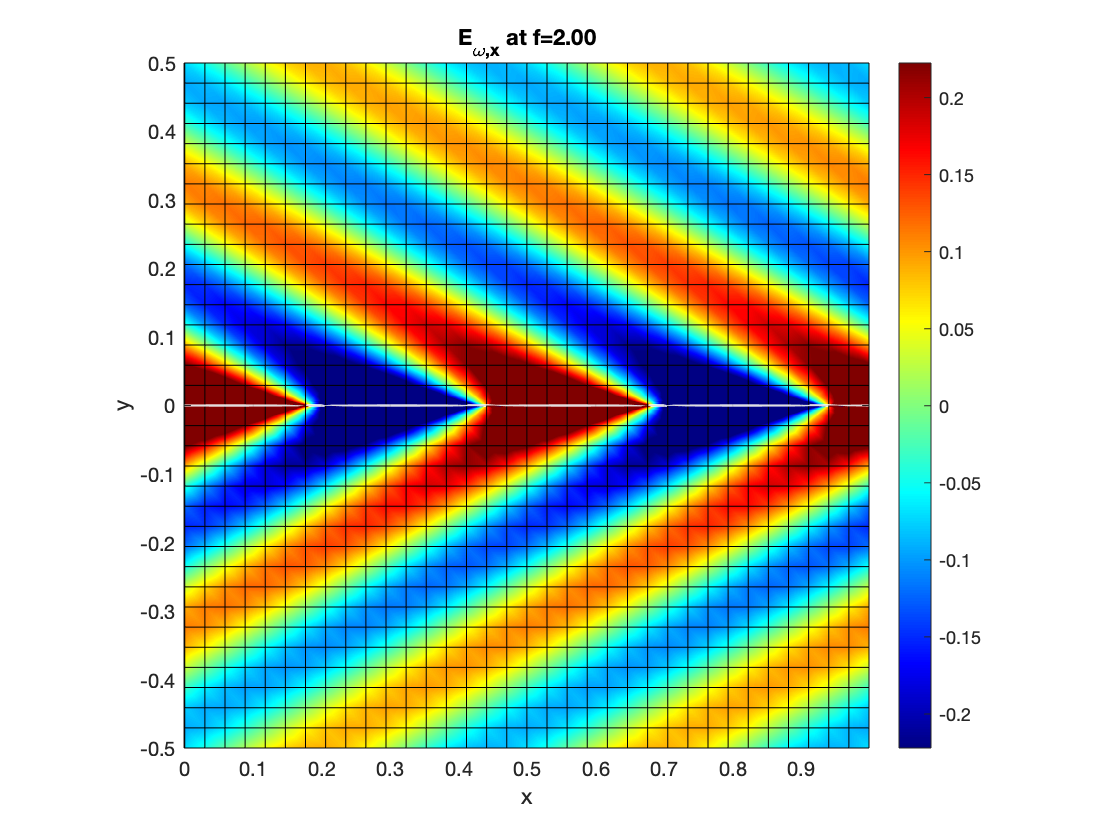

fsurf(real(Ewx),[0,1,-0.5,+0.5])
box on; axis equal; shading interp; colormap jet; colorbar; view(2);
title(sprintf('E_{\\omega,x} at f=%.2f',f)); xlabel('x'); ylabel('y');
caxis(caxis/50)


% Plot Ewy
Ewy=eval(Ew(2))

$$Ewy = -\frac{\sqrt{3}\,{\mathrm{e}}^{-4\,\pi \,\left(x\,\mathrm{i}+\sqrt{3}\,\left|y\right|\,\mathrm{i}\right)}\,\mathrm{sign}\left(y\right)\,\left(\pi \,\sqrt{3}\,\left|y\right|\,\left(8+8\,\mathrm{i}\right)+1-\mathrm{i}\right)}{192\,\pi^{3/2}\,{\left|y\right|}^{2}\,\sqrt{4\,\pi }\,\sqrt{\frac{\sqrt{3}}{3\,\left|y\right|}}}$$

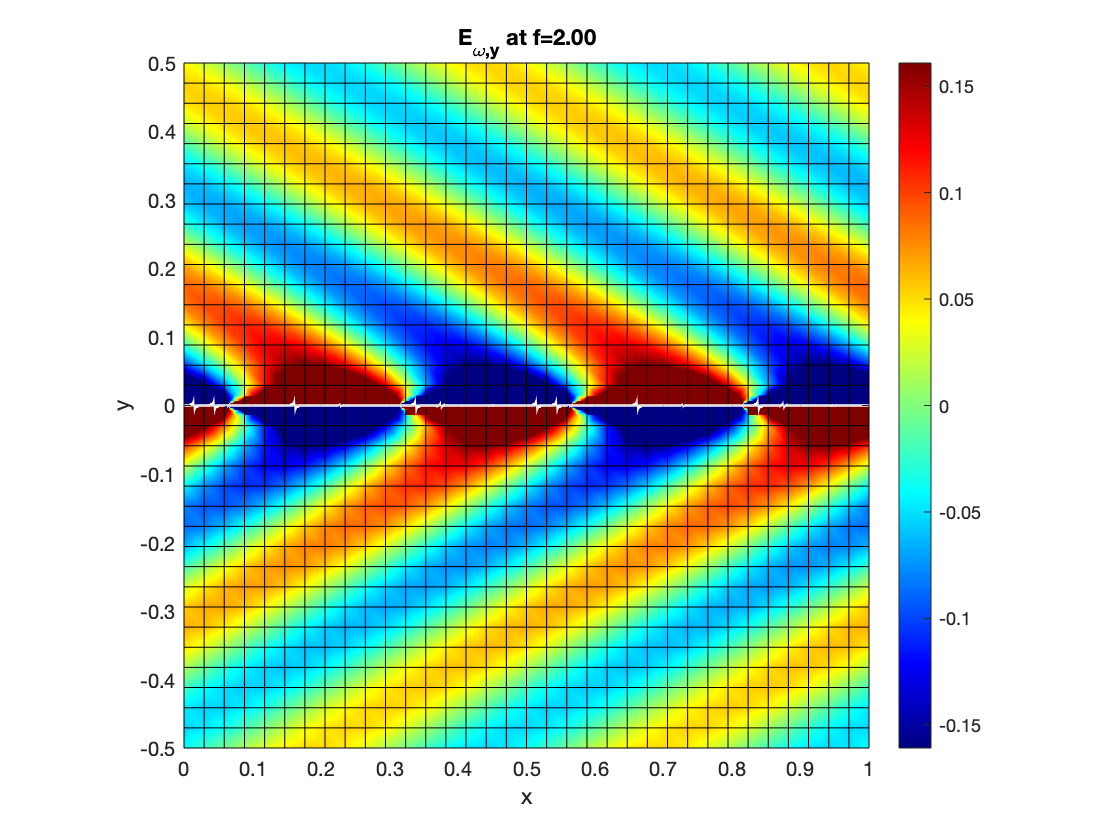

fsurf(real(Ewy),[0,1,-0.5,+0.5])
box on; axis equal; shading interp; colormap jet; colorbar; view(2);
title(sprintf('E_{\\omega,y} at f=%.2f',f)); xlabel('x'); ylabel('y');
caxis(caxis/500)


% Plot Hwz
Hwz=eval(Hw)

$$Hwz = -\frac{\sqrt{3}\,{\mathrm{e}}^{-4\,\pi \,\left(x\,\mathrm{i}+\sqrt{3}\,\left|y\right|\,\mathrm{i}\right)}\,\mathrm{sign}\left(y\right)\,\left(\pi \,\sqrt{3}\,\left|y\right|\,\left(8+8\,\mathrm{i}\right)+1-\mathrm{i}\right)}{48\,\pi^{3/2}\,{\left|y\right|}^{2}\,\sqrt{4\,\pi }\,\sqrt{\frac{\sqrt{3}}{3\,\left|y\right|}}}$$

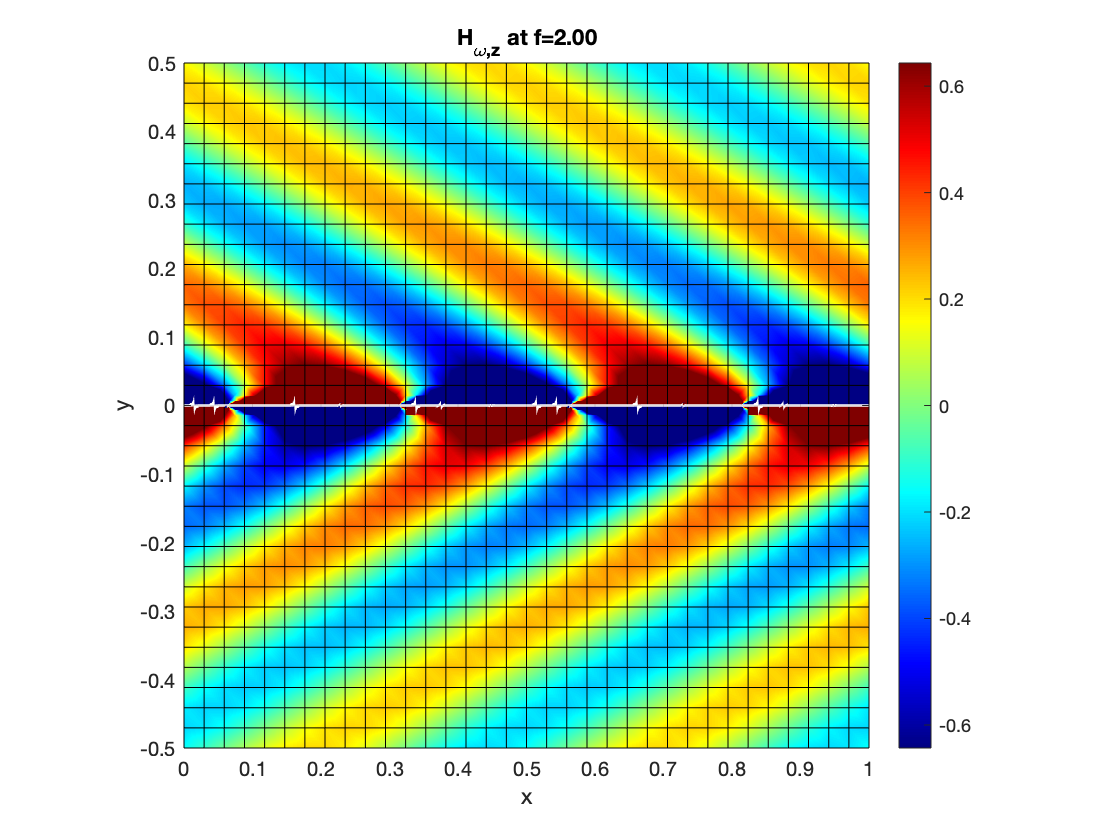

fsurf(real(Hwz),[0,1,-0.5,+0.5])
box on; axis equal; shading interp; colormap jet; colorbar; view(2);
title(sprintf('H_{\\omega,z} at f=%.2f',f)); xlabel('x'); ylabel('y');
caxis(caxis/500)